# Übung 7

## 7.1 Startup

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
clc
format compact

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnis-Ausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF. Geben Sie dieses PDF (und nur dieses PDF) zur Kontrolle ab (moodle/Laufwerk/email).

## 7.2 Berechnung des Scheitelfaktors

Der Scheitelfaktor einer Wechselspannung u(t) ist der Spitzenwert der Wechselspannung, dividiert durch deren Effektivwert:


$$ U_{eff} = \sqrt{ \frac{1}{T} \int_0^T u^2(t) dt } $$


Berechnen Sie symbolisch den Scheitelfaktor für eine sinusförmige Wechselspannung.

syms u t T

u = sin(2*pi*t/T);
disp('u(t) = ');

u(t) = 


pretty(u);

   / 2 pi t \
sin| ------ |
   \    T   /




Ueff = sqrt( 1/T * int(u^2,t,0,T) );
disp('Ueff = ');

Ueff = 


pretty(Ueff);

sqrt(2)
-------
   2




C = 1/Ueff;
disp('C = ');

C = 


pretty(C);

sqrt(2)



## 7.3 Sinus / Kosinustransformation

Gegeben ist die Funktion f(t) mit


$$ f(t) = \sin (\omega t) $$


Multiplizieren Sie dieses Signal mit

a)      $$ \sin(\omega t) $$

b)      $$ \sin(2 \omega t) $$

c)      $$ \cos(\omega t) $$

d)      $$ \cos(2 \omega t) $$

und zeigen Sie jeweils

1. die Funktionsgraphen beider beteiligter Funktionen (*figure*, *subplot*, *ezplot*),

2. den Funktionsgraphen des Produktes

3. das unbestimmte Integral des Produktes (*pretty*),

4. das bestimmte Integral des Produktes im Intervall 0..2*pi (als Zahlenwert).

HINWEISE: Setzen Sie $$\omega = const. = 1 $$. Entwickeln Sie zur Bearbeitung der Punkte 1. bis 4. eine *function*.

Zur Anzeige der *function* an dieser Stelle verwenden Sie die Funktion "type [funktionsname](http://funktionsname).m"

% Hier wird der Quellcode der Funktion ausgegeben
type SymbInt.m

% Given two functions f and g 
% will draw f, g and f*g in the interval [0 2*pi]
function SymbInt( fx, gx, x )

    % Multiplikation beider Funktionen
    hx = fx * gx;

    % Print string literal into console ?!?
    disp('Y =');

    % start a figure
    figure;

    % draw the function f
    subplot(3, 1, 1);
    ezplot(fx, [0 2*pi]);

    % draw the function g
    subplot(3, 1, 2);
    ezplot(gx, [0 2*pi] );

    % draw the function f * g
    subplot(3, 1, 3);
    ezplot(hx, [0 2*pi] );

    % int - definite and indefinite integrals
    Hx = int(hx, x);
    pretty(Hx);

    Ybest = int(hx, x, 0, 2*pi)
end


syms w t
w = 1;

% first use sin() for both f and g
f = sin(w*t)

$$f = \sin\left(t\right)$$

Y =


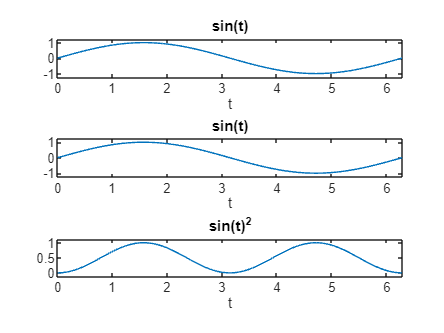

t   sin(2 t)
- - --------
2       4



$$Ybest = \pi$$

g = sin(w*t);
SymbInt(f, g, t);

Y =


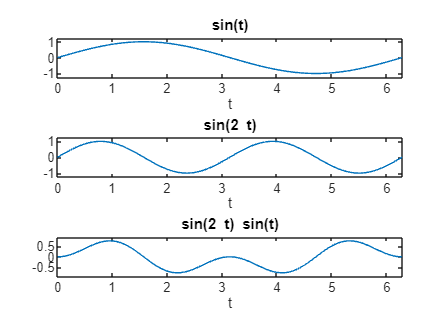

        3
2 sin(t)
---------
    3



$$Ybest = 0$$

% switch it up! use sin(2*w*t) for g
g = sin(2*w*t);
SymbInt(f, g, t);

Y =


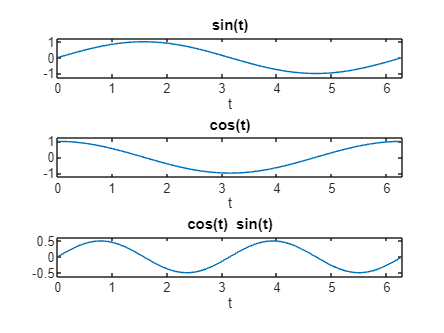

      2
sin(t)
-------
   2



$$Ybest = 0$$

% switch it up! use cos(w*t) for g
g = cos(w*t);
SymbInt(f, g, t);

Y =


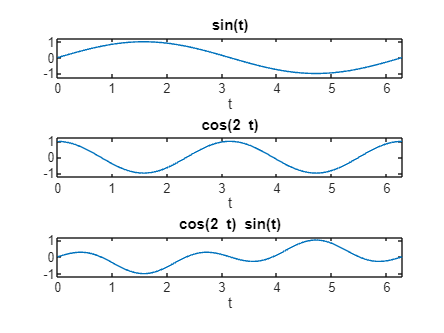

                 3
         2 cos(t)
cos(t) - ---------
             3



$$Ybest = 0$$

g = cos(2*w*t);
SymbInt(f, g, t);

e) Diskutieren Sie die Ergebnisse.

...

f) Welches Ergebnisse erwarten Sie für das Signal

$$ f(t) = 1/2 \sin(\omega t) + 1/4 \cos(2*\omega t) + 1 $$ ?

...

g) Prüfen Sie Ihre Vermutungen, analog zum oben angewandten Verfahren

Y =


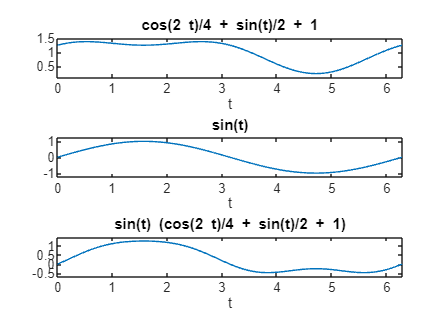

                                     3
t   3 cos(t)   cos(t) sin(t)   cos(t)
- - -------- - ------------- - -------
4       4            4            6



$$Ybest = \frac{\pi }{2}$$

f = 1/2*sin(w*t) + 1/4*cos(2*w*t) + 1;
g = sin(w*t);
SymbInt(f, g, t);

Y =


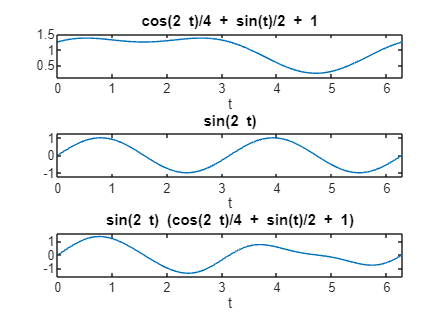

        2         3         4
5 sin(t)    sin(t)    sin(t)
--------- + ------- - -------
    4          3         4



$$Ybest = 0$$

g = sin(2*w*t);
SymbInt(f, g, t);

Y =


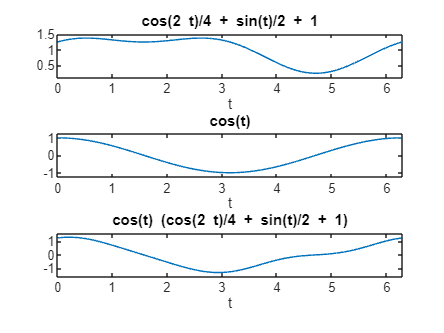

                 2         3
5 sin(t)   sin(t)    sin(t)
-------- + ------- - -------
    4         4         6



$$Ybest = 0$$

g = cos(w*t);
SymbInt(f, g, t);

Y =


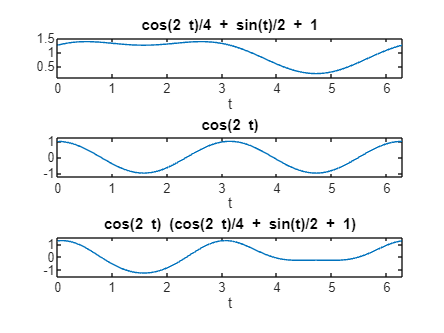

                                     3         3
t   cos(t)   7 cos(t) sin(t)   cos(t)    cos(t)  sin(t)
- + ------ + --------------- - ------- + --------------
8      2            8             3             4



$$Ybest = \frac{\pi }{4}$$

g = cos(2*w*t);
SymbInt(f, g, t);